clc; clear; close all;clc; clear; close all;

% -----------------------------
% Cargar datos como tabla
% -----------------------------
filename = 'Five_times_Kinematics_HT_Query_MATLAB_SIN_OUTLIERS.xlsx';
numericData = readtable(filename);

X = numericData{:,:};      % Solo datos numéricos
[n, p] = size(X);

% Parámetros de bootstrap
B = 500;                   % número de réplicas
alpha = 0.05;              % nivel de significancia
lower_p = alpha/2;
upper_p = 1 - alpha/2;

% -----------------------------
% Chi-square plots bivariados
% Comparar variable 3 con todas las siguientes (desde la 4)
% -----------------------------
dim_interes = 83;

for j = 84:p
    % Extraer submatriz bivariada
    X_sub = [X(:, dim_interes), X(:, j)];  % n x 2

    % Estadísticos de ajuste
    mean_vec = mean(X_sub);
    cov_mat   = cov(X_sub);
    inv_cov   = pinv(cov_mat);

    % Distancias de Mahalanobis observadas
    D2_obs = zeros(n,1);
    for i = 1:n
        d = X_sub(i,:) - mean_vec;
        D2_obs(i) = d * inv_cov * d';
    end
    D2_obs_sorted = sort(D2_obs);

    % Cuantiles teóricos chi² (df = 2)
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % -----------------------------
    % Bootstrap paramétrico para la banda
    % -----------------------------
    D2_boot = zeros(n, B);
    for b = 1:B
        % Simular n observaciones MVN
        Xb = mvnrnd(mean_vec, cov_mat, n);
        % Calcular distancias y ordenar
        db_mat = Xb - mean_vec;  % n x 2
        D2b = sum((db_mat * inv_cov) .* db_mat, 2);  % n x 1
        D2_boot(:,b) = sort(D2b);
    end

    % Calcular percentiles fila a fila
    lower_env = quantile(D2_boot, lower_p, 2);
    upper_env = quantile(D2_boot, upper_p, 2);

    % -----------------------------
    % Gráfico con banda de confianza
    % -----------------------------
    varName_i = numericData.Properties.VariableNames{dim_interes};
    varName_j = numericData.Properties.VariableNames{j};

    figure;
    hold on;
    % Banda gris
    fill( [chi2_q; flipud(chi2_q)], ...
          [lower_env; flipud(upper_env)], ...
          [0.9 0.9 0.9], 'EdgeColor','none');
    % Línea identidad
    plot(chi2_q, chi2_q, 'r--', 'LineWidth',1.2);
    % Datos observados
    plot(chi2_q, D2_obs_sorted, 'bo', 'MarkerFaceColor','b');
    hold off;

    axis equal; grid on;
    xlabel('\chi^2 teóricos (df = 2)');
    ylabel('Distancias de Mahalanobis ordenadas');
    title(sprintf('Chi-square plot: %s vs %s', varName_i, varName_j));
    legend('Banda 95%','y = x','Datos', 'Location','best');
end



% -----------------------------
% Cargar datos como tabla
% -----------------------------
filename = 'Five_times_Kinematics_HT_Query_MATLAB_SIN_OUTLIERS.xlsx';
numericData = readtable(filename);  % Esto carga los nombres de las variables también

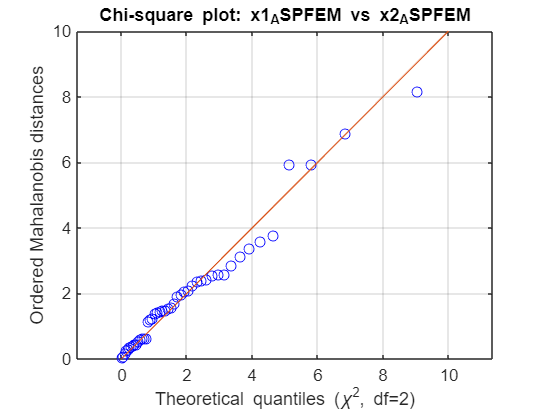

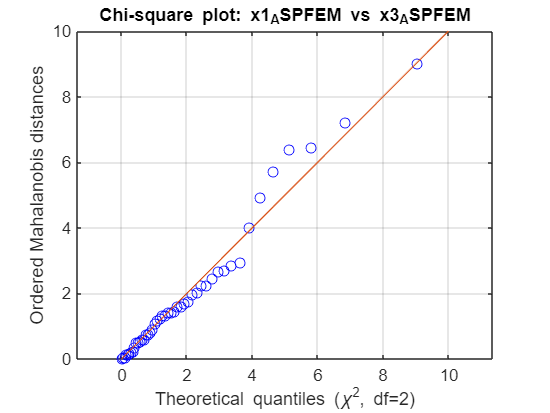

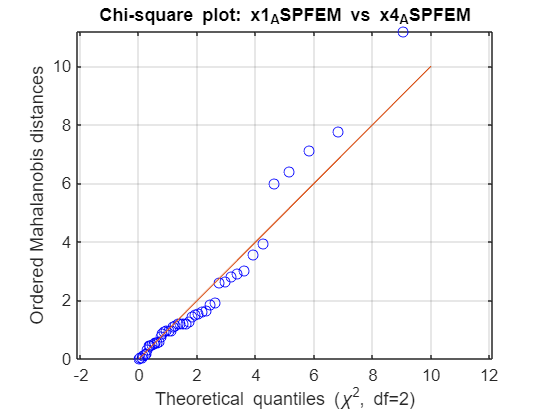

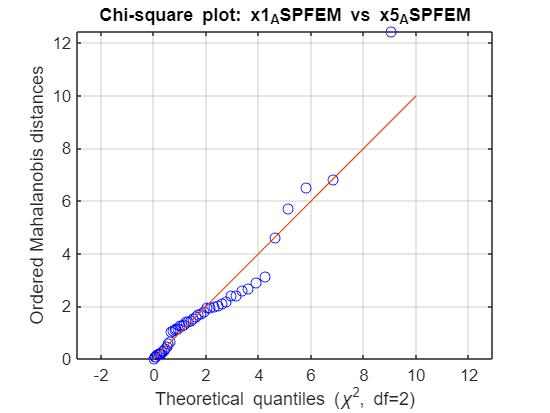


X = numericData{:,:};  % Extraer solo los datos numéricos
[n, p] = size(X);

% -----------------------------
% Chi-square plot
% Comparar variable 8 con todas las siguientes (desde la 9)
% -----------------------------
dim_interes = 83;

for j = 84:p
    % Extraer los datos de las columnas como vectores
    X_sub = [X(:, dim_interes), X(:, j)];  % n x 2

    % Calcular vector de medias y matriz de covarianza
    mean_vec = mean(X_sub);
    cov_mat = cov(X_sub);
    inv_cov = inv(cov_mat);

    % Calcular distancias de Mahalanobis
    mahal_dist = zeros(n, 1);
    for i = 1:n
        diff = X_sub(i, :) - mean_vec;
        mahal_dist(i) = diff * inv_cov * diff';
    end

    % Cuantiles teóricos de chi-cuadrado con 2 grados de libertad
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % Obtener nombres de las variables
    varName_i = numericData.Properties.VariableNames{dim_interes};
    varName_j = numericData.Properties.VariableNames{j};

    % Graficar Chi-square plot
    figure;
    plot(chi2_q, sort(mahal_dist), 'bo');
    hold on;
    refline(1, 0);  % línea identidad
    xlabel('Theoretical quantiles (\chi^2, df=2)');
    ylabel('Ordered Mahalanobis distances');
    title(['Chi-square plot: ', varName_i, ' vs ', varName_j]);
    axis equal;
    grid on;
end